% Lab 3 - Task 1 input-output steady-state DC behaviour
ports = serialportlist;    % find all serial ports
pb = PyBench('/dev/cu.usbmodem2066339B594B2');    % create a PyBench object


% measure the steady-state DC output vs input
pb.samp_freq = 100;    % take sample at 100Hz
NSTEPS = 25;    % take 25 steps in input
input = zeros(NSTEPS, 1);    % reserve 25 x 1 vector memory
output = zeros(NSTEPS, 1);    % ... faster than appending one-by-one
tic    % start timer
disp('Sweeping drive voltage for DC steady-state characteristics');

Sweeping drive voltage for DC steady-state characteristics


for i = 1:NSTEPS
    v = (i-1) * 2.5 / NSTEPS;    % voltage to drive input
    input(i) = v;
    pb.dc(v);    % write to DC to drive bulb
    pause(0.5);    % wait for output to settle
    data = pb.get_block(10);    % make 10 measurements
    output(i) = mean(data);    % ... to average
end
pb.dc(0.0);    % turn bulb off
toc    % stop timer

Elapsed time is 15.641004 seconds.


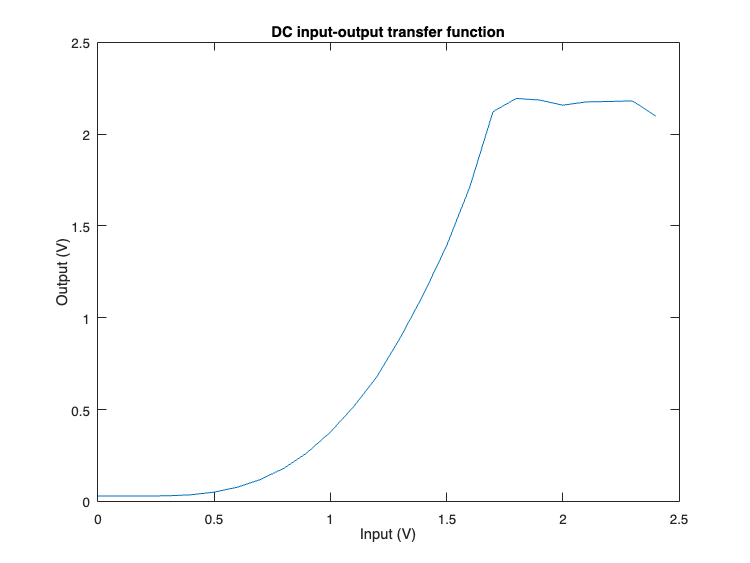


figure;
plot(input, output);    % plot output vs input
xlabel('Input (V)');    % Label the axes
ylabel('Output (V)');
title('DC input-output transfer function');

fclose(instrfind());    % close the port